clc, clear all, close all
%-------------Input--------------
%Señal analoga
Ax = 3;
fx = 3400;
%Carrier
fc = 1000e3;
Tc = 1/fc;
Ac = 10;
pc = 0;
tc = linspace(0,25*Tc,500);
%Indice de modulacion
n = 5; % n <= 2
%-----Proceso
%Datos analogos
Tx = 1/fx;
tx = linspace(0,3*Tx,500);
xt = Ax *sin(2*pi*fx*tx)

xt =          0    0.1133    0.2264    0.3392    0.4516    0.5633    0.6741    0.7841    0.8929    1.0004    1.1065    1.2110    1.3138    1.4147    1.5136    1.6103    1.7048    1.7968    1.8862    1.9730    2.0569    2.1379    2.2159    2.2907    2.3622    2.4304    2.4951    2.5562    2.6137    2.6674    2.7174    2.7634    2.8056    2.8437    2.8778    2.9077    2.9335    2.9551    2.9726    2.9857    2.9946    2.9993    2.9996    2.9957    2.9875    2.9750    2.9583    2.9374    2.9123    2.8830


%señal fm con carrier}
carrier = Ac*sin(2*pi*fc*tc);
FM = Ac*sin(2*pi*fc*tc+n*xt)

FM =          0    7.7155    9.8183    4.8030   -3.6667   -9.4855   -8.5407   -1.5871    6.4376    9.9982    6.7759   -0.9277   -7.9660   -9.8555   -5.5742    2.0573    8.3833    9.8041    5.7330   -1.3760   -7.6596   -9.9977   -7.4776   -1.5530    4.9383    9.2155    9.7146    6.5251    1.0849   -4.5720   -8.6208   -9.9991   -8.5816   -5.0232   -0.4115    4.1089    7.6257    9.6089    9.9266    8.7669    6.5153    3.6314    0.5503   -2.3781   -4.9159   -6.9355   -8.4021   -9.3485   -9.8494   -9.9999


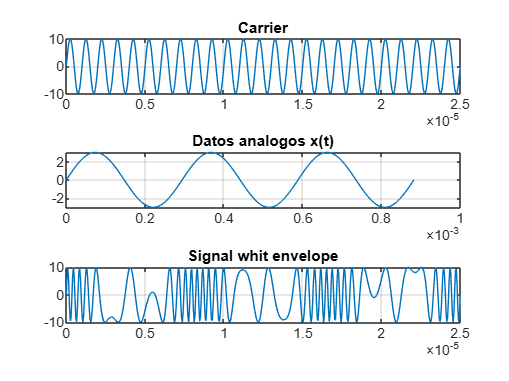

figure(2)
subplot(3,1,1), plot(tc, carrier), title('Carrier'), grid on
subplot(3,1,2), plot(tx, xt), title('Datos analogos x(t)'), grid on
subplot(3,1,3), plot(tc, FM), title('Señal FM'), grid on
plot(tc, FM), title('Signal whit envelope'), grid on